path = 'Unziped/A5_20190604/fichier1';
extension = 'npy';
folderlist = dir([path,'/*',extension]);
% Déclaration d'une structure pour stocker les variables
data = struct();

% Boucle pour traiter chaque fichier
for ifile = 1:length(folderlist)
    % Affichage du nom de fichier sans l'extension
    filename = folderlist(ifile).name(1:(length(folderlist(ifile).name)-4));
    disp(filename);
    
    % Lecture des données du fichier
    filepath = fullfile(path, folderlist(ifile).name);
    data.(filename) = readNPY(filepath);
end

MarkOnSignal
SampleRate
firstsignal
mark
signal
timestamp


electrodes = data.signal(:,[3,14,16,18]);

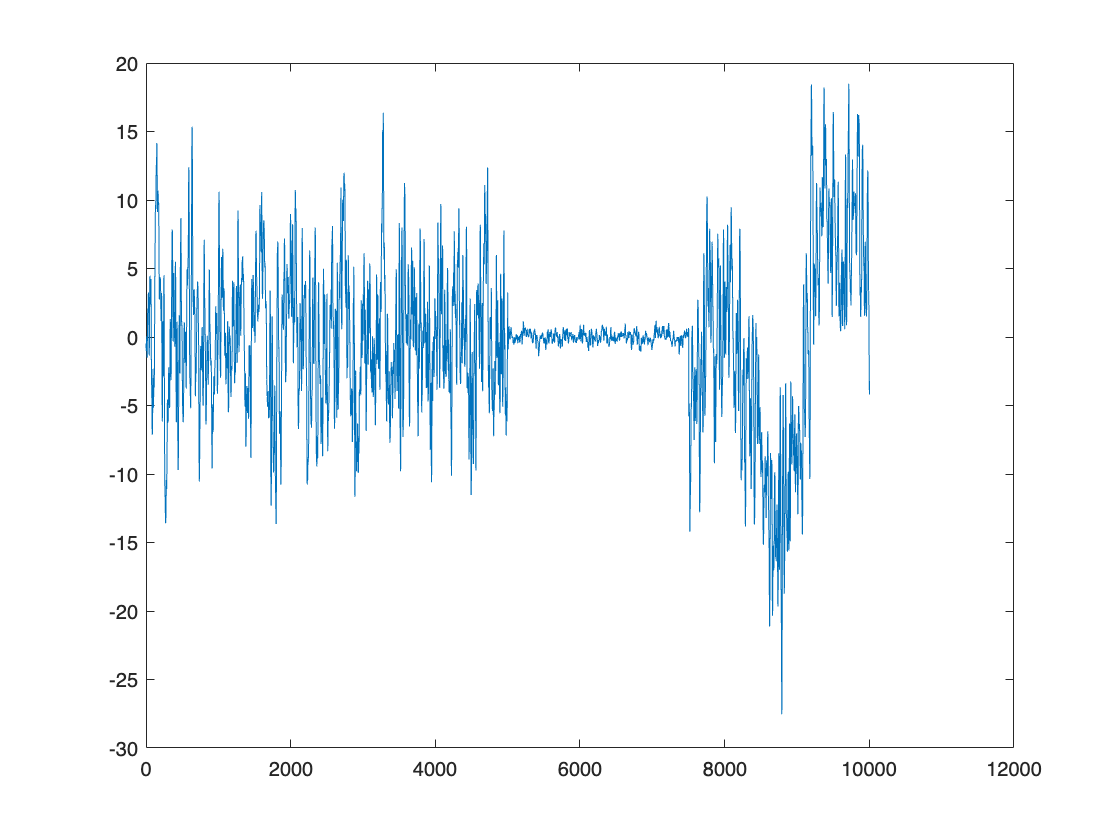

signal = [electrodes(23100:25600,1);...
    electrodes(23100:25600,2);...
    electrodes(23100:25600,3);...
    electrodes(23100:25600,4)];
plot(signal)

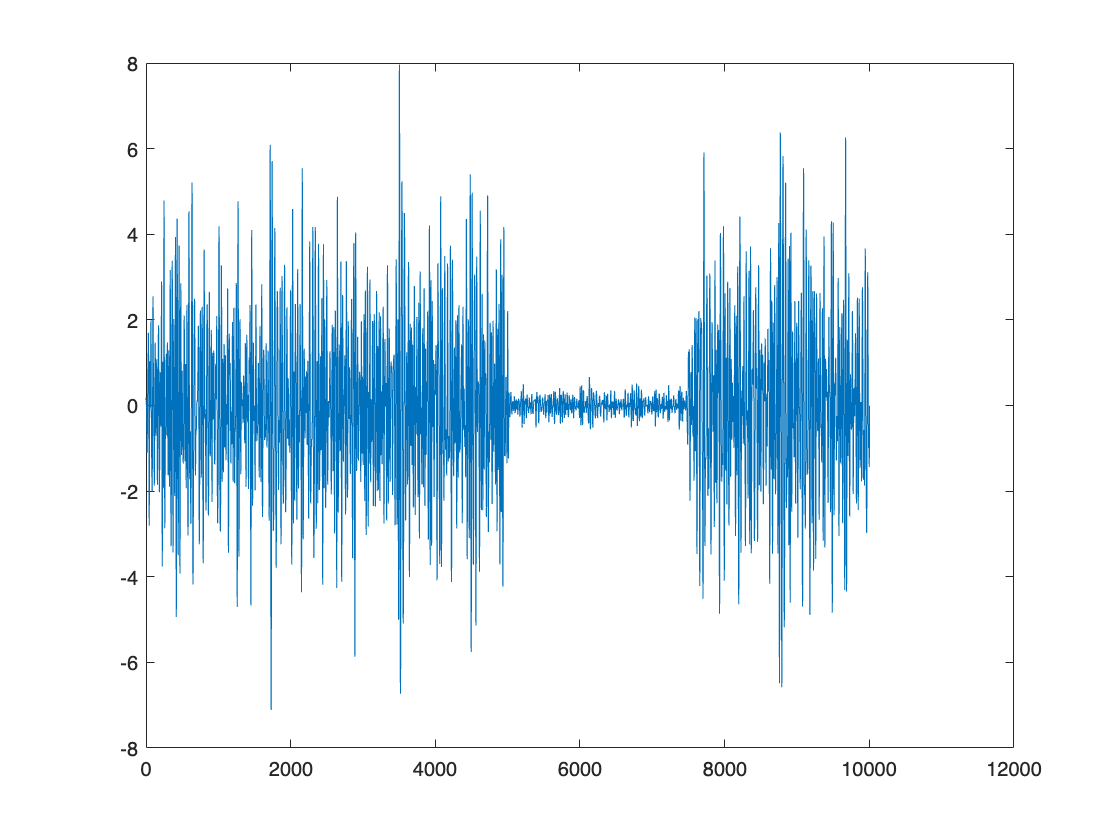

fs = 500; %fréquence d'échantillonnage
fc = 35;
[b,a] = butter(4,fc/(fs/2),"low"); %filtre passe-bas (supprimer bruit à haute fréquence)
eeg_data_filtered = filtfilt(b,a,signal); % appliquer filtre aux données EEG

fc = 12 ;
[b,a] = butter(4,fc/(fs/2),"high"); %filtre passe-haut (supprimer bruit à basse fréquence)
eeg_data_filtered = filtfilt(b,a, eeg_data_filtered);
plot(eeg_data_filtered)

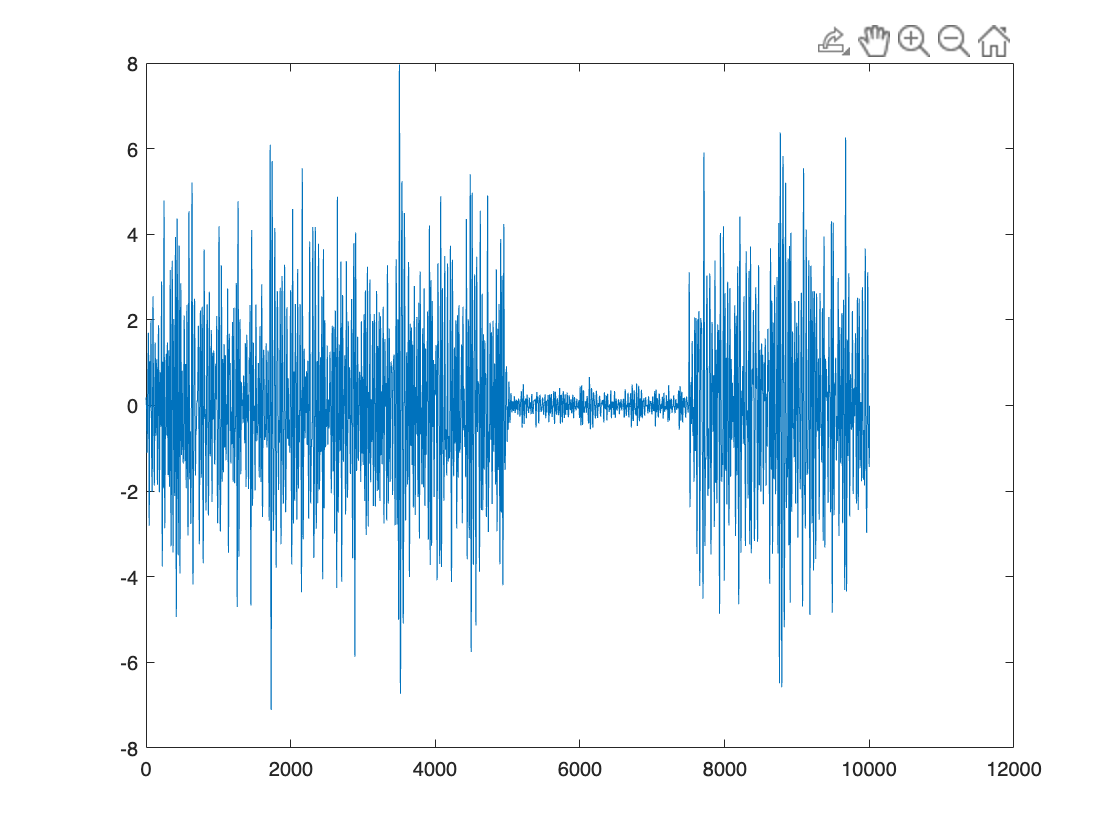

% filtrage signal par signal
sig_final = 0;
for ele = 1:4
    fs = 500; %fréquence d'échantillonnage
    fc = 35;
    [b,a] = butter(4,fc/(fs/2),"low"); %filtre passe-bas (supprimer bruit à haute fréquence)
    eeg_data_filtered = filtfilt(b,a,electrodes(23100:25600,ele)); % appliquer filtre aux données EEG
    
    fc = 12 ;
    [b,a] = butter(4,fc/(fs/2),"high"); %filtre passe-haut (supprimer bruit à basse fréquence)
    eeg_data_filtered = filtfilt(b,a, eeg_data_filtered);
    sig_final = [sig_final;eeg_data_filtered];
end
sig_final = sig_final(2:length(sig_final));
% aucune différence observée lors de la comparaison du filtrage du signal final 
% et du filtrage signal par signal (voir ci dessous)
plot(sig_final) 

Aucune différence observée lors de la comparaison du filtrage du signal final et du filtrage signal par signal (voir ci dessus). On va donc choisir de tracer le scalogramme en filtrant le signal final (les signaux des quatres électrodes réunis).

### Scalogrammes

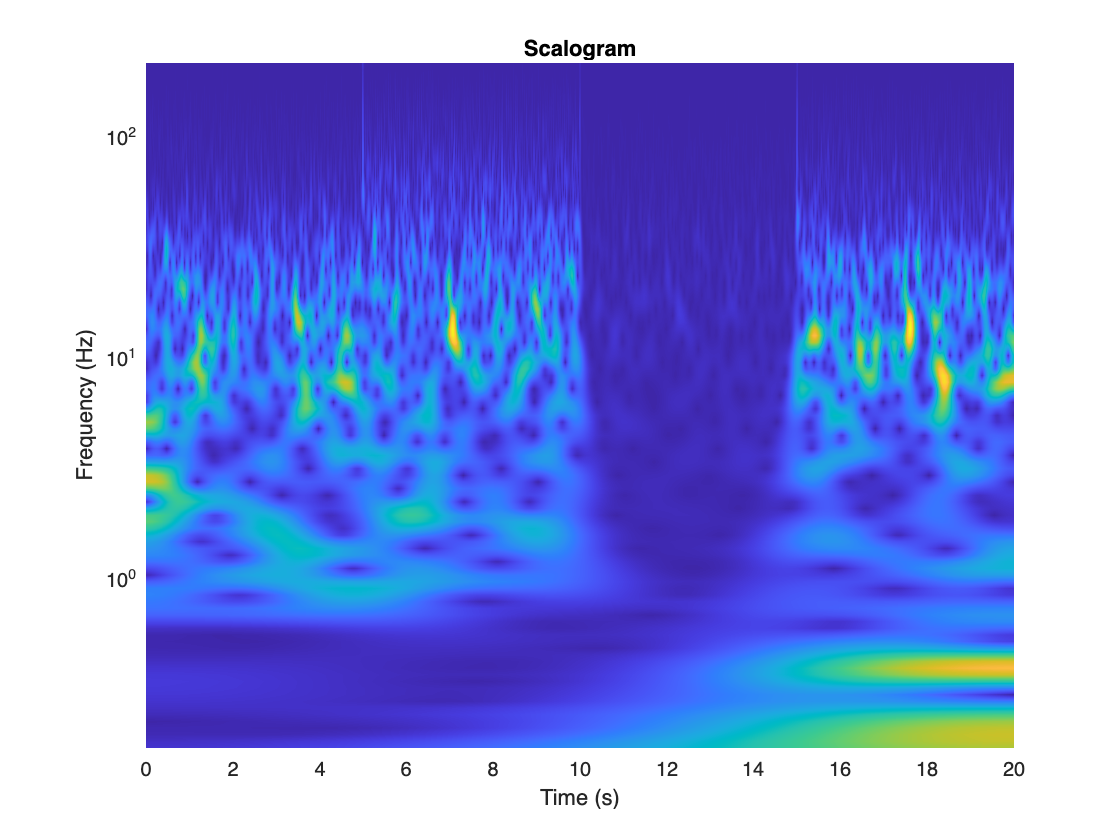

%
% Tracé du scalogrmme sans filtrage préalable
%
% Concaténation des signaux des différentes électrodes
sig = [electrodes(23100:25600,1);...
    electrodes(23100:25600,2);...
    electrodes(23100:25600,3);...
    electrodes(23100:25600,4)];
% Transformée en ondelettes du signal
fb = cwtfilterbank(signallength = length(sig),...
    samplingfrequency=500, ...
    wavelet="Morse");
[cfs,frq] = wt(fb,sig);
t = (0:(length(sig)-1))/500;
h = figure;
pcolor(t,frq,abs(cfs));
set(gca,'yscale','log');shading interp;axis tight;
title('Scalogram');xlabel('Time (s)');ylabel('Frequency (Hz)');

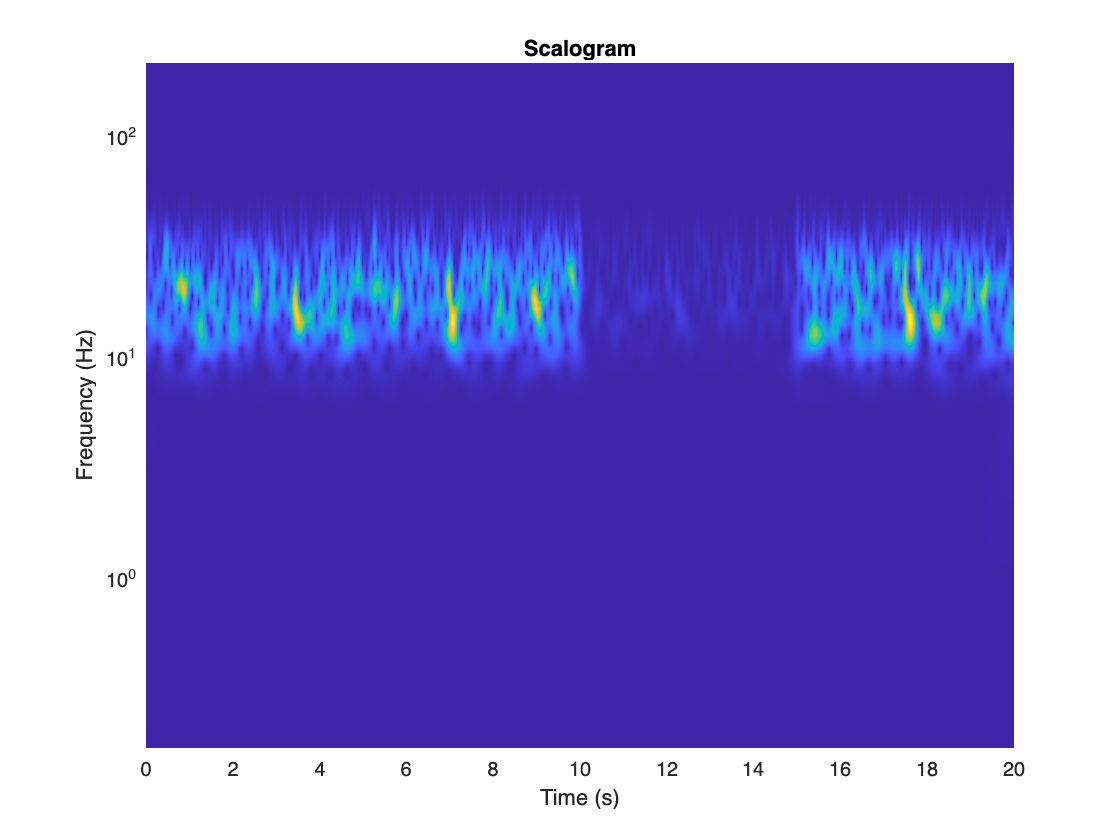

%
% Tracé du scalogramme après filtrage du signal
%
% Concaténation des signaux des différentes électrodes
sig = [electrodes(23100:25600,1);...
    electrodes(23100:25600,2);...
    electrodes(23100:25600,3);...
    electrodes(23100:25600,4)];
fs = 500; %fréquence d'échantillonnage
fc = 35;
[b,a] = butter(4,fc/(fs/2),"low"); %filtre passe-bas (supprimer bruit à haute fréquence)
eeg_data_filtered = filtfilt(b,a,sig); % appliquer filtre aux données EEG

fc = 12 ;
[b,a] = butter(4,fc/(fs/2),"high"); %filtre passe-haut (supprimer bruit à basse fréquence)
eeg_data_filtered = filtfilt(b,a, eeg_data_filtered);
% Transformée en ondelettes du signal
fb = cwtfilterbank(signallength = length(eeg_data_filtered),...
    samplingfrequency=500, ...
    wavelet="Morse");
[cfs,frq] = wt(fb,eeg_data_filtered);
% 
t = (0:(length(eeg_data_filtered)-1))/500;
h = figure;
pcolor(t,frq,abs(cfs));
set(gca,'yscale','log');shading interp;axis tight;
title('Scalogram');xlabel('Time (s)');ylabel('Frequency (Hz)');